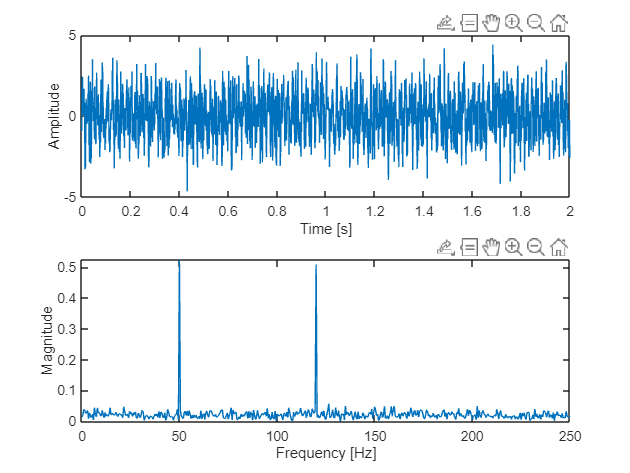

fs = 1000;
t_end = 2;
f1 = 50;
f2 = 120;

t = 0:1/fs:t_end-1/fs;

x = sin(2*pi*f1*t) + sin(2*pi*f2*t) + randn(size(t));

X = fft(x);
n = length(x);
f = (0:n-1)*(fs/n);

magnitude = abs(X)/n;

subplot(2,1,1);
plot(t, x);
xlabel('Time [s]');
ylabel('Amplitude');

subplot(2,1,2);
plot(f, magnitude);
xlabel('Frequency [Hz]');
ylabel('Magnitude');
axis([0 250 0 max(magnitude)]);